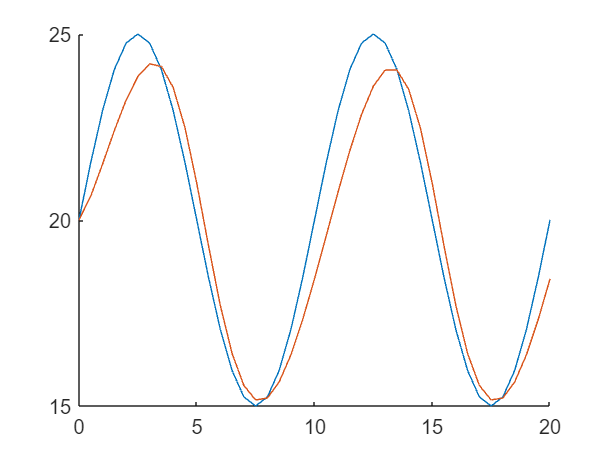

veh = Vehicle4COMPASS('a_max',5,'delta',4);

simTimeStep = 0.5;
simTimeTot = 20;
time_series = 0:simTimeStep:simTimeTot;
vehSpd_des = 5*sin(2*pi*0.1*time_series) + 20;
vehSpd_log = zeros(size(time_series));
vehSpd_log(1) = 20;
figure 
hold on
plot(time_series,vehSpd_des);
for i = 2:length(time_series)
    acc = veh.idm(vehSpd_log(i-1),33,150,vehSpd_des(i));
    vehSpd_log(i) = vehSpd_log(i-1) + acc*simTimeStep;
end
plot(time_series,vehSpd_log)
hold off